clear all;
close all;
clc;

load JND_first.mat;
test_data = JND_result_first(1,:);
% distmodel = fitdist(test_data',"GeneralizedExtremeValue")

distribution_model_array = ["HalfNormal","Rayleigh","Exponential",...
    "GeneralizedExtremeValue","GeneralizedPareto","Stable","tLocationScale",...
    "BirnbaumSaunders","ExtremeValue",...
    "Gamma",...
    "Logistic","Loglogistic","LogNormal","Nakagami",...
    "Normal","Poisson","Rician","Weibull"];

for i = 1:length(distribution_model_array)
    distmodel = fitdist(test_data', distribution_model_array(i));
end

clear all;
close all;
clc;

load JND_first.mat;
load JND_second.mat;
load JND_third.mat;



data_QF = JND_result_first(1, :);
data_distortion_level = 101 - data_QF;
histogram(data_distortion_level);
hold on;
ylim([0 10]);
xlim([0 100]);
h_gca = gca;
h = h_gca.Children;
h.FaceColor = [.9 .9 .9];
h.EdgeColor = [.9 .9 .9];
[N,edges] = histcounts(data_distortion_level);
bin_center = edges + 0.5;
bin_center(end) = [];
plot(bin_center,N,'o');
hold off;
n = length(data_distortion_level);
prob = N / n ;
bar(bin_center,prob,'hist');
hold on;
h_gca = gca;
h = h_gca.Children;
h.FaceColor = [0.9 0.9 0.9];
xlabel('Distortion level');
ylabel('Probability Density');
% ylim([0 0.4]);
xlim([0 100]);
pd_GEV = fitdist(data_distortion_level','GeneralizedExtremeValue');
pdf_GEV = pdf(pd_GEV,0:100);
plot(0:100,pdf_GEV);
% SUR there (for GEV)
obj_cdf = cdf(pd_GEV, 0:100);
% SUR curve.
SUR = 1 - obj_cdf;
plot(0:100,SUR)
ecdf(data_distortion_level,'function','survivor')
legend("Data samples", "Data fitting with GEV");
title("Data fitting for first JND with image index 1");
hold off;



data_QF = JND_result_second(1, :);
data_distortion_level = 101 - data_QF;
histogram(data_distortion_level);
hold on;
ylim([0 10]);
xlim([0 100]);
h_gca = gca;
h = h_gca.Children;
h.FaceColor = [.9 .9 .9];
h.EdgeColor = [.9 .9 .9];
[N,edges] = histcounts(data_distortion_level);
bin_center = edges + 0.5;
bin_center(end) = [];
plot(bin_center,N,'o');
hold off;
n = length(data_distortion_level);
prob = N / n ;
bar(bin_center,prob,'hist');
hold on;
h_gca = gca;
h = h_gca.Children;
h.FaceColor = [0.9 0.9 0.9];
xlabel('Distortion level');
ylabel('Probability Density');
% ylim([0 0.4]);
xlim([0 100]);
pd_GEV = fitdist(data_distortion_level','GeneralizedExtremeValue');
pdf_GEV = pdf(pd_GEV,0:100);
plot(0:100,pdf_GEV);
% SUR there (for GEV)
obj_cdf = cdf(pd_GEV, 0:100);
% SUR curve.
SUR = 1 - obj_cdf;
plot(0:100,SUR)
ecdf(data_distortion_level,'function','survivor')
legend("Data samples", "Data fitting with GEV");
title("Data fitting for first JND with image index 1");
hold off;


data_QF = JND_result_third(1, :);
data_distortion_level = 101 - data_QF;
histogram(data_distortion_level);
hold on;
ylim([0 10]);
xlim([0 100]);
h_gca = gca;
h = h_gca.Children;
h.FaceColor = [.9 .9 .9];
h.EdgeColor = [.9 .9 .9];
[N,edges] = histcounts(data_distortion_level);
bin_center = edges + 0.5;
bin_center(end) = [];
plot(bin_center,N,'o');
hold off;
n = length(data_distortion_level);
prob = N / n ;
bar(bin_center,prob,'hist');
hold on;
h_gca = gca;
h = h_gca.Children;
h.FaceColor = [0.9 0.9 0.9];
xlabel('Distortion level');
ylabel('Probability Density');
% ylim([0 0.4]);
xlim([0 100]);
pd_GEV = fitdist(data_distortion_level','GeneralizedExtremeValue');
pdf_GEV = pdf(pd_GEV,0:100);
plot(0:100,pdf_GEV);
% SUR there (for GEV)
obj_cdf = cdf(pd_GEV, 0:100);
% SUR curve.
SUR = 1 - obj_cdf;
plot(0:100,SUR)
ecdf(data_distortion_level,'function','survivor')

legend("Data samples", "Data fitting with GEV");
title("Data fitting for first JND with image index 1");
hold off;


clear all;
close all;
clc;

load JND_first.mat;
load JND_second.mat;
load JND_third.mat;

data_test_QF = JND_result_first(1, :)
cdfplot(data_test_QF)
data_test_distortion_level = 101 - data_test_QF
cdfplot(data_test_distortion_level);
xlim([0 100])
% ecdf(data_test_distortion_level);
% xlim([0 100])
[f, x] = ecdf(data_test_distortion_level);
plot(x, 1-f)
xlim([0 100])

ecdf(data_test_distortion_level,'function','survivor')
xlim([0 100])

    figure
point = [0.7, 0.5];   % Here the point that will have the reference lines
axLims = [0 1 -2 2];  %[x-min, x-max, y-min, y-max] axis limits
plot(point(1), point(2), 'o')
xlim(axLims(1:2)); 
ylim(axLims(3:4)); 
hold on
plot([point(1), point(1)], [axLims(3), point(2)], 'k-')  %vertical line
plot([axLims(1), point(1)], [point(2), point(2)], 'k-')  %horizontal line

clear all;
close all;
clc;

load JND_first.mat;
load JND_second.mat;
load JND_third.mat;

data_QF = JND_result_first(11, :);
data_distortion_level = 101 - data_QF;
% histogram(data_distortion_level);
% hold on;
% ylim([0 10]);
% xlim([0 100]);
% h_gca = gca;
% h = h_gca.Children;
% h.FaceColor = [.9 .9 .9];
% h.EdgeColor = [.9 .9 .9];
[N,edges] = histcounts(data_distortion_level);
bin_center = edges + 0.5;
bin_center(end) = [];
% plot(bin_center,N,'o');
% hold off;
n = length(data_distortion_level);
prob = N / n ;
bar(bin_center,prob,'hist');
hold on;
h_gca = gca;
h = h_gca.Children;
h.FaceColor = [0.9 0.9 0.9];
xlabel('Distortion level');
ylabel('Probability Density');
xlim([0 100]);
pd_GEV = fitdist(data_distortion_level','GeneralizedExtremeValue');
pdf_GEV = pdf(pd_GEV,0:100);
plot(0:100,pdf_GEV,'g');
% SUR there (for GEV)
obj_cdf = cdf(pd_GEV, 0:100);
% SUR curve.
SUR = 1 - obj_cdf;
plot(0:100,SUR)
ecdf(data_distortion_level,'function','survivor')
legend("Histogram", "PDF", "SUR", "Empirical SUR",'AutoUpdate', 'off', 'Location','west');
% title("Data fitting for first JND with image index 3");
% hold off;
inverse_distortion_result = icdf(pd_GEV, 0.25);

point = [inverse_distortion_result, 0.75];   % Here the point that will have the reference lines
plot(point(1), point(2), 'o')
plot([point(1), point(1)], [0, point(2)], 'k--')  %vertical line
plot([0, point(1)], [point(2), point(2)], 'k--')  %horizontal line
xlabel('Distortion Level');
ylabel('');
hold off;

data_QF = JND_result_second(11, :);
data_distortion_level = 101 - data_QF;
% histogram(data_distortion_level);
% hold on;
% ylim([0 10]);
% xlim([0 100]);
% h_gca = gca;
% h = h_gca.Children;
% h.FaceColor = [.9 .9 .9];
% h.EdgeColor = [.9 .9 .9];
[N,edges] = histcounts(data_distortion_level);
bin_center = edges + 0.5;
bin_center(end) = [];
% plot(bin_center,N,'o');
% hold off;
n = length(data_distortion_level);
prob = N / n ;
bar(bin_center,prob,'hist');
hold on;
h_gca = gca;
h = h_gca.Children;
h.FaceColor = [0.9 0.9 0.9];
xlabel('Distortion level');
ylabel('Probability Density');
xlim([0 100]);
pd_GEV = fitdist(data_distortion_level','GeneralizedExtremeValue');
pdf_GEV = pdf(pd_GEV,0:100);
plot(0:100,pdf_GEV,'g');
% SUR there (for GEV)
obj_cdf = cdf(pd_GEV, 0:100);
% SUR curve.
SUR = 1 - obj_cdf;
plot(0:100,SUR)
ecdf(data_distortion_level,'function','survivor')
legend("Histogram", "PDF", "SUR", "Empirical SUR",'AutoUpdate', 'off', 'Location','west');
% title("Data fitting for second JND with image index 3");
% hold off;
inverse_distortion_result = icdf(pd_GEV, 0.25);

point = [inverse_distortion_result, 0.75];   % Here the point that will have the reference lines
plot(point(1), point(2), 'o')
plot([point(1), point(1)], [0, point(2)], 'k--')  %vertical line
plot([0, point(1)], [point(2), point(2)], 'k--')  %horizontal line
xlabel('Distortion Level');
ylabel('');
hold off;

data_QF = JND_result_third(11, :);
data_distortion_level = 101 - data_QF;
% histogram(data_distortion_level);
% hold on;
% ylim([0 10]);
% xlim([0 100]);
% h_gca = gca;
% h = h_gca.Children;
% h.FaceColor = [.9 .9 .9];
% h.EdgeColor = [.9 .9 .9];
[N,edges] = histcounts(data_distortion_level);
bin_center = edges + 0.5;
bin_center(end) = [];
% plot(bin_center,N,'o');
% hold off;
n = length(data_distortion_level);
prob = N / n ;
bar(bin_center,prob,'hist');
hold on;
h_gca = gca;
h = h_gca.Children;
h.FaceColor = [0.9 0.9 0.9];
xlabel('Distortion level');
ylabel('Probability Density');
xlim([0 100]);
pd_GEV = fitdist(data_distortion_level','GeneralizedExtremeValue');
pdf_GEV = pdf(pd_GEV,0:100);
plot(0:100,pdf_GEV,'g');
% SUR there (for GEV)
obj_cdf = cdf(pd_GEV, 0:100);
% SUR curve.
SUR = 1 - obj_cdf;
plot(0:100,SUR)
ecdf(data_distortion_level,'function','survivor')
legend("Histogram", "PDF", "SUR", "Empirical SUR",'AutoUpdate', 'off', 'Location','west');
% title("Data fitting for third JND with image index 3");
% hold off;
inverse_distortion_result = icdf(pd_GEV, 0.25);

point = [inverse_distortion_result, 0.75];   % Here the point that will have the reference lines
plot(point(1), point(2), 'o')
plot([point(1), point(1)], [0, point(2)], 'k--')  %vertical line
plot([0, point(1)], [point(2), point(2)], 'k--')  %horizontal line
xlabel('Distortion Level');
ylabel('');
hold off;

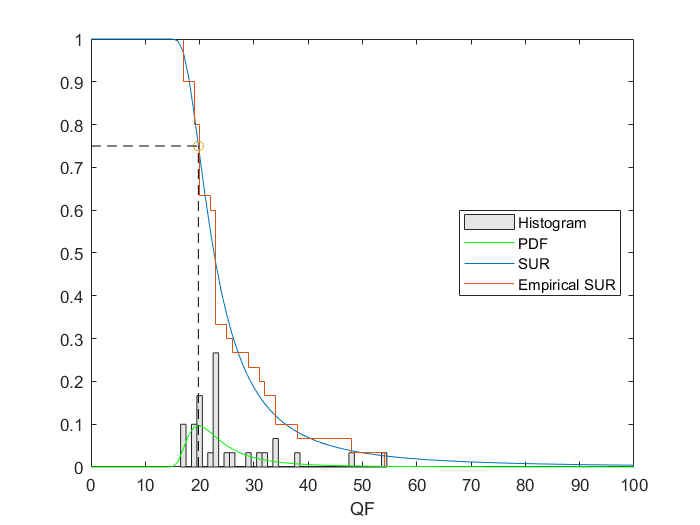

clear all;

close all;
clc;

load JND_first.mat;
load JND_second.mat;
load JND_third.mat;

 data_QF = JND_result_first(10, :);
    % data_distortion_level = 101 - data_QF;
    % histogram(data_distortion_level);
    % hold on;
    % ylim([0 10]);
    % xlim([0 100]);
    % h_gca = gca;
    % h = h_gca.Children;
    % h.FaceColor = [.9 .9 .9];
    % h.EdgeColor = [.9 .9 .9];
    [N,edges] = histcounts(data_QF);
    bin_center = edges + 0.5;
    bin_center(end) = [];
    % plot(bin_center,N,'o');
    % hold off;
    n = length(data_QF);
    prob = N / n ;
    bar(bin_center,prob,'hist');
    hold on;
    h_gca = gca;
    h = h_gca.Children;
    h.FaceColor = [0.9 0.9 0.9];
    xlabel('QF');
    ylabel('Probability Density');
    xlim([0 100]);
    pd_GEV = fitdist(data_QF','GeneralizedExtremeValue');
    pdf_GEV = pdf(pd_GEV,0:100);
    plot(0:100,pdf_GEV,'g');
    % SUR there (for GEV)
    cdf_GEV = cdf(pd_GEV, 0:100);
    % SUR curve.
    SUR = 1 - cdf_GEV;
    plot(0:100,SUR)
    ecdf(data_QF,'function','survivor')
    legend("Histogram", "PDF", "SUR", "Empirical SUR",'AutoUpdate', 'off', 'Location','east');
    % title("Data fitting for first JND with image index 3");
    % hold off;
    inverse_distortion_result = icdf(pd_GEV, 0.25);
    
    point = [inverse_distortion_result, 0.75];   % Here the point that will have the reference lines
    plot(point(1), point(2), 'o')
    plot([point(1), point(1)], [0, point(2)], 'k--')  %vertical line
    plot([0, point(1)], [point(2), point(2)], 'k--')  %horizontal line
    xlabel('QF')
    ylabel('');
    hold off;